# [Lithium-ion Batteries](https://apmonitor.com/pds/index.php/Main/LithiumIonBatteries)

Physical and chemical properties of the Lithium-ion silicate cathodes are used to predict the crystal structure of a Lithium-ion battery material as monoclinic, orthorhombic and triclinic. This case study demonstrates how [feature engineering](https://apmonitor.com/pds/index.php/Main/FeatureEngineering) improves the classification results.

**Background**

[Lithium-ion batteries](https://en.wikipedia.org/wiki/Lithium-ion_battery) are commonly used for portable electronics, electric vehicles, and aerospace applications. During discharge, Lithium ions move from the negative electrode through an electrolyte to the positive electrode to create a voltage and current. During recharging, the ions migrate back to the negative electrode. The crystal structure (monoclinic, orthorhombic, triclinic) is available for 339 different chemicals that contain lithium. Available properties are:

- Materials Id: unique ID of the material from materialsproject.org

- Formula: chemical formula of the compound

- Space group: symmetry group of a three-dimensional crystal pattern

- Formation Energy (eV): energy required to produce the material from standard elements

- E Above Hull (eV): energy released if compound is decomposed into the most stable compounds

- [Band Gap (eV)](https://en.wikipedia.org/wiki/Band_gap): energy range in a solid where no electronic states can exist. A larger band gap indicates that the compound is worse at conducting electricity or heat.

- Nsites: Number of atoms in the unit cell of the crystal

- Density (gm/cc): mass per volume of bulk crystalline materials

- Volume: unit cell volume of the material

- Has Bandstructure: Boolean (True / False) variable for bandstructure

**Objective**

Predict the crystal structure type (monoclinic, orthorhombic, triclinic) from Lithium-ion physical and chemical compound information.

[Lithium-ion Chemical Properties and Crystal Structure Data](https://apmonitor.com/pds/uploads/Main/lithium_ion.txt)

url = 'http://apmonitor.com/pds/uploads/Main/lithium_ion.txt';

% Read Data
data = readtable(url,'VariableNamingRule','preserve');
data

data = 339×11 table
    Materials Id          Formula         Spacegroup    Formation Energy (eV)    E Above Hull (eV)    Band Gap (eV)    Nsites    Density (gm/cc)    Volume    Has Bandstructure    Crystal System
    _____________    _________________    __________    _____________________    _________________    _____________    ______    _______________    ______    _________________    ______________

    {'mp-849394'}    {'Li2MnSiO4'    }    {'Pc'   }            -2.699                  0.006              3.462          16           2.993         178.51        {'TRUE' }        {'monoclinic'}
    {'mp-783909'}    {'


% Observe data types
for i=1:size(data,2)
    varClasses = class(data.(i));
    disp(data.Properties.VariableNames(i));
    disp(varClasses);
end

    {'Materials Id'}



cell


    {'Formula'}



cell


    {'Spacegroup'}



cell


    {'Formation Energy (eV)'}



double


    {'E Above Hull (eV)'}



double


    {'Band Gap (eV)'}



double


    {'Nsites'}



double


    {'Density (gm/cc)'}



double


    {'Volume'}



double


    {'Has Bandstructure'}



cell


    {'Crystal System'}



cell


## Categorical encoding methods

**1. One Hot Encoding**

Method: Encode each category value into a binary vector, with size = # of distinct values. For more information on encoding, see this [link.](https://towardsdatascience.com/understanding-feature-engineering-part-2-categorical-data-f54324193e63)

Example: Has Bandstructure column has 2 distinct values, True and False. Create a new column where 1 = True and 0 = False.

Pros: simple and rugged method to get categorical features into unique and useful numerical features

Cons: m unique values results in m unique new features. This is fine when there are only 2-3 unique values (such as hi/lo, yes/no), but creates issues when there are more. Can't handle new categories that weren't in training data, and easily overfit. Sparse data.

**2. Encode to ordinal variables**

Method: assign each unique value to a unique number.

Example: Spacegroup = Pc is assigned to 0, Spacegroup = P21/c is assigned to 1, etc.

Pros: simple and quick, 1 column in -> 1 column out

Cons: residual "structure" (number assigned is arbitrary, and it leads algorithms to assume that a Spacegroup with a value of 20 is higher value than a Spacegroup of value 1)

**3. Other methods**

Primarily involve prior knowledge about dataset. Encode with own algorithm to include closely related features.

Variation on One Hot Encoding for large numbers of unique values: classify infrequent instances into "rare" category. May lose some granularity and important info, but also allows for new categories that aren't in training data

### **'Materials Id' column**

The code below detects the number of occurances in the Materials Id column

[uniqueXX,~,J] = unique(string(data.("Materials Id")));
occ = histcounts(J,1:numel(uniqueXX));
disp(max(occ))

     2



339 unique values for 339 unique entries; there is no useful information in this column and it can be dropped

tbl = removevars(data,'Materials Id');
tbl

tbl = 339×10 table
         Formula         Spacegroup    Formation Energy (eV)    E Above Hull (eV)    Band Gap (eV)    Nsites    Density (gm/cc)    Volume    Has Bandstructure    Crystal System
    _________________    __________    _____________________    _________________    _____________    ______    _______________    ______    _________________    ______________

    {'Li2MnSiO4'    }    {'Pc'   }            -2.699                  0.006              3.462          16           2.993         178.51        {'TRUE' }        {'monoclinic'}
    {'Li2MnSiO4'    }    {'P21/c'}            -2.696                  0.008              2.879          32   

### `'Has Bandstructure'`** column**

Make a bar chart of the 'Has Bandstructure' column

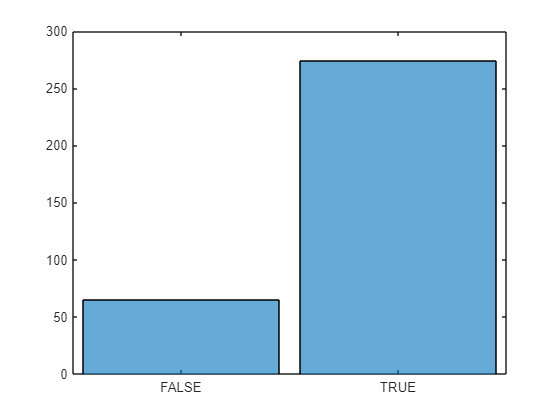

histogram(categorical(tbl.('Has Bandstructure')))

2 unique values, True and False. Classic example of when to use one-hot encoding.

tbl.('Has Bandstructure') = double(string(tbl.('Has Bandstructure')) == 'TRUE');
tbl

tbl = 339×10 table
         Formula         Spacegroup    Formation Energy (eV)    E Above Hull (eV)    Band Gap (eV)    Nsites    Density (gm/cc)    Volume    Has Bandstructure    Crystal System
    _________________    __________    _____________________    _________________    _____________    ______    _______________    ______    _________________    ______________

    {'Li2MnSiO4'    }    {'Pc'   }            -2.699                  0.006              3.462          16           2.993         178.51            1            {'monoclinic'}
    {'Li2MnSiO4'    }    {'P21/c'}            -2.696                  0.008              2.879          32   

### `'Spacegroup'`** column**

Make a bar chart of the 'Spacegroup' column

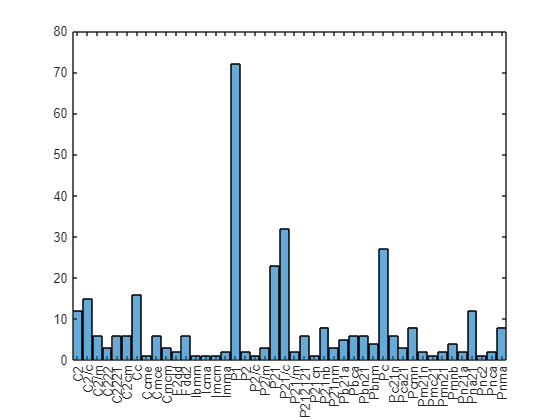

histogram(categorical(tbl.('Spacegroup')))

44 unique values, with most of them occuring multiple times

#### **Option 1:** 

One-hot encoding will result in 44 new feature columns; inefficient and memory-intensive.

dummyVars = dummyvar(categorical(data.Spacegroup));
spacegroupNames = categories(categorical(data.Spacegroup));
dummyVarsTable = array2table(dummyVars, 'VariableNames', strcat("Spacegroup_",spacegroupNames));
dummyVarsTable

dummyVarsTable = 339×44 table
    Spacegroup_C2    Spacegroup_C2/c    Spacegroup_C2/m    Spacegroup_C222    Spacegroup_C2221    Spacegroup_C2cm    Spacegroup_Cc    Spacegroup_Ccme    Spacegroup_Cmce    Spacegroup_Cmcm    Spacegroup_F2dd    Spacegroup_Fdd2    Spacegroup_Ibmm    Spacegroup_Icma    Spacegroup_Imcm    Spacegroup_Imma    Spacegroup_P1    Spacegroup_P2    Spacegroup_P2/c    Spacegroup_P2/m    Spacegroup_P21    Spacegroup_P21/c    Spacegroup_P21/m    Spacegroup_P212121    Spacegroup_P21cn    Spacegroup_P21nb    Spacegroup_P21nm


% This method is not used
tbl = [data,dummyVarsTable];
tbl

tbl = 339×55 table
    Materials Id          Formula         Spacegroup    Formation Energy (eV)    E Above Hull (eV)    Band Gap (eV)    Nsites    Density (gm/cc)    Volume    Has Bandstructure    Crystal System    Spacegroup_C2    Spacegroup_C2/c    Spacegroup_C2/m    Spacegroup_C222    Spacegroup_C2221    Spacegroup_C2cm    Spacegroup_Cc    Spacegroup_Ccme    Spacegroup_Cmce    Spacegroup_Cmcm    Spacegroup_F2dd    Spacegroup_Fdd2    Spacegroup_Ibmm    Spacegroup_Icma    Spacegroup_Imcm    Spacegroup_Imma    Spacegroup_P1

#### **Option 2:** 

Encode to ordinal numbers. Will possibly work, but does leave a residual structure that may affect model performance

tbl.('Spacegroup (ordinal)') = grp2idx(tbl.Spacegroup);

% Can also order by most common to least common
[~,~,rank] = unique(tbl.Spacegroup);
disp([tbl.Spacegroup, string(rank)]);

    "Pc"         "32"
    "P21/c"      "22"
    "Cc"         "7" 
    "C2/c"       "2" 
    "C2/c"       "2" 
    "C2"         "1" 
    "P21"        "21"
    "P21/c"      "22"
    "C2/c"       "2" 
    "Cc"         "7" 
    "P21/c"      "22"
    "C2/c"       "2" 
    "P21/c"      "22"
    "C2/m"       "3" 
    "P21"        "21"
    "C2"         "1" 
    "P21/c"      "22"
    "Cc"         "7" 
    "P21/c"      "22"
    "C2/c"       "2" 
    "P21"        "21"
    "P21"        "21"
    "C2"         "1" 
    "P21"        "21"
    "C2"         "1" 
    "Cc"         "7" 
    "Pc"         "32"
    "Pc"         "32"
    "P21/c"      "22"
    "P2/m"       "20"
    "P21"        "21"
    "Pc"         "32"
    "C2/c"       "2" 
    "C2"         "1" 
    "P21"        "21"
    "C2/m"       "3" 
    "C2/c"       "2" 
    "P21/c"      "22"
    "P21/c"      "22"
    "Pc"         "32"
    "P21"        "21"
    "P2/c"       "19"
    "Cc"         "7" 
    "Pc"         "32"
    "Cc"         "7" 
    "Cc"  

rank gives you the number of time spacegroups repeats while refering to each column. There are 32 Pc, 22 P21/c, etc.

### **'Formula' column**

Determine how many unique labels and the occurance there is for the Formula column.

[uniqueXX,~,J] = unique(string(data.('Formula'))); % Determine the unique values
occ = histcounts(J,1:numel(uniqueXX)+1); % Deterimine the occurance of the uniqe values
occ = occ';

% Combine the arrays into a table and display results
tbll = array2table([uniqueXX, occ]);
tbll.(2) = double(tbll.(2));
display(sortrows(tbll,2,'descend'));

  114×2 table

           Var1           Var2
    __________________    ____

    "LiFeSiO4"             42 
    "LiCoSiO4"             29 
    "Li2FeSiO4"            15 
    "Li2CoSiO4"            14 
    "Li2MnSiO4"            12 
    "LiMnSiO4"             12 
    "Li3Co2(SiO4)2"        10 
    "Li3Fe2(SiO4)2"        10 
    "LiFe(SiO3)2"          10 
    "Li2Mn(SiO3)2"          7 
    "Li3Mn2(SiO4)2"         7 
    "LiFeSi3O8"             7 
    "Li2Fe(SiO3)2"          6 
    "LiMn(SiO3)2"           5 
    "Li2Co(Si2O5)2"         4 
    "Li2Co(SiO3)2"          4 
    "Li2Fe(Si2O5)2"         4 
    "Li2Fe(Si2O5)3"         4 
    "Li2FeSi3O8"            4 
    "Li5Fe5Si7O24"          4 
    "Li2Co2(SiO3)3"         3 
    "Li2Co2Si2O7"           3 
    "Li2Fe2(SiO3)3"         3 
    "Li2Fe2Si2O7"           3 
    "Li2Mn(Si2O5)2"         3 
    "Li2Mn2(SiO3)

114 unique values, most only occuring once. One-hot encoding is out of the question

**Option 1,2:** one-hot encoding and ordinal number encoding become inefficient with such variety.

#### **Option 3:** 

Use domain knowledge to create additional features. For example, we can look at the LiFeSiO4 formula, and turn it into 4 new columns, each one indicating how many of each atom are in the formula (for example, {Li: 1, Fe: 1, Si: 1, O: 4})

Download the the [parse_formula package](https://www.mathworks.com/matlabcentral/fileexchange/117670-parse_formula). Extract the file, and place the folder's content in the working directory of this script. You may be required to restart your MATLAB program after the contents are in the working directory.

% Download the parse_formula package
url = "https://www.mathworks.com/matlabcentral/mlc-downloads/downloads/3a9590ad-98f5-4d34-854d-08145dcff069/822a0985-5b3f-4b99-96e8-293176ade0b6/packages/zip";
filename = "parse_formula.zip";

if ~exist(filename,"file")
    % Save, unzip, and delete the file
    websave(filename, url);
    unzip(filename);
end

chem_data = array2table(zeros(length(tbl.Formula),6),'VariableNames',{'Li','Mn','Si','O','Fe','Co'}); % table full of zeros for each chemical

% update the table above with the correct number of atoms in each chemical
for i=1:size(tbl.Formula,1)
    [~,chem_tbl,~,~] = parse_formula(tbl.Formula(i));
    for j=1:size(chem_tbl,1)
        for k=1:6
            if chem_tbl(j).element == chem_data.Properties.VariableNames(k)
                chem_data(i,k).(1) = chem_tbl(j).count; 
            end
        end
    end
end

% Combine the generate table with our previous table
table = [tbl,chem_data]

table = 339×62 table
    Materials Id          Formula         Spacegroup    Formation Energy (eV)    E Above Hull (eV)    Band Gap (eV)    Nsites    Density (gm/cc)    Volume    Has Bandstructure    Crystal System    Spacegroup_C2    Spacegroup_C2/c    Spacegroup_C2/m    Spacegroup_C222    Spacegroup_C2221    Spacegroup_C2cm    Spacegroup_Cc    Spacegroup_Ccme    Spacegroup_Cmce    Spacegroup_Cmcm    Spacegroup_F2dd    Spacegroup_Fdd2    Spacegroup_Ibmm    Spacegroup_Icma    Spacegroup_Imcm    Spacegroup_Imma    Spacegroup_P1<

### **'Crystal System' column**

This is the target column, and there are 3 different types of crystal structures we're trying to classify. To properly transform this to numerical data, we have to understand if we are working on a multi-class problem or a multi-label problem.

- A multi-class problem is one in which there is only one distinct type of classification for each row. For example, a fruit is either an apple or an orange, but cannot be both. For a multi-class problem, the target value should be a single value, such as a 0 for apple and 1 for orange. In other words, it would be encoded to ordinal numbers.

- A multi-label problem is one in which there are possibly multiple labels for each row. For example, classifying pictures of apples and oranges can include a picture of an apple alone, an orange alone, or both an apple and an orange. For a multi-label problem, the target value should be a vector representation, such as [1,0] for apple, [0,1] for orange, and [1,1] for both apple and orange. In other words, we would have to one-hot encode the target feature.

Since the crystal system structure is unique, this is a multi-class problem. The target output should be encoded to a 0, 1, or 2. If it were a multi-label problem, the target output would have to be encoded to a vector of length 3.

labelencoder = categorical(table.('Crystal System')); % convert to categorical variable
table.('Crystal System (#)') = double(labelencoder); % convert categorical variable to numerical
one_hot = dummyvar(labelencoder); % get one-hot encoding

% extract one-hot encoded columns
table.('monoclinic') = one_hot(:,1); 
table.('orthorhombic') = one_hot(:,2);
table.('triclinic') = one_hot(:,3);
table

table = 339×66 table
    Materials Id          Formula         Spacegroup    Formation Energy (eV)    E Above Hull (eV)    Band Gap (eV)    Nsites    Density (gm/cc)    Volume    Has Bandstructure    Crystal System    Spacegroup_C2    Spacegroup_C2/c    Spacegroup_C2/m    Spacegroup_C222    Spacegroup_C2221    Spacegroup_C2cm    Spacegroup_Cc    Spacegroup_Ccme    Spacegroup_Cmce    Spacegroup_Cmcm    Spacegroup_F2dd    Spacegroup_Fdd2    Spacegroup_Ibmm    Spacegroup_Icma    Spacegroup_Imcm    Spacegroup_Imma    Spacegroup_P1<

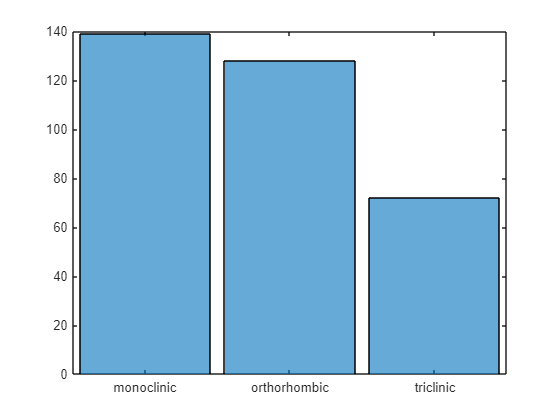

% Histrogram
histogram(categorical(table.('Crystal System')));

### **Test Performance**

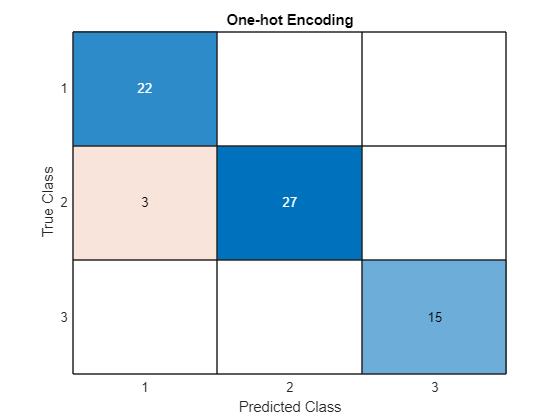

% Create list of labels used for Option 2
ord_feat = {'Formation Energy (eV)','E Above Hull (eV)','Band Gap (eV)',...
            'Nsites','Density (gm/cc)','Volume','Has Bandstructure',...
            'Spacegroup (ordinal)','Li','Mn','Si','O','Fe','Co'};

% Grab labels
labels = {'Crystal System (#)'};

% Option 1 (One-hot Encoding)
X = table(:,1:55);
y = table.("Crystal System (#)");

%% Split Data for Option 1
cv = cvpartition(size(table.("Formation Energy (eV)"),1),'Holdout',0.2);
train_idx = training(cv);
test_idx = test(cv);
Xtrain = X(train_idx,:);
ytrain = y(train_idx,:);
Xtest = X(test_idx,:);
ytest = y(test_idx,:);

%% Train and test model for Option 1
model = fitctree(Xtrain,ytrain);
yP = predict(model,Xtest);

%% Show confusion chart for Option 1
confusionchart(ytest,yP);
title('One-hot Encoding');

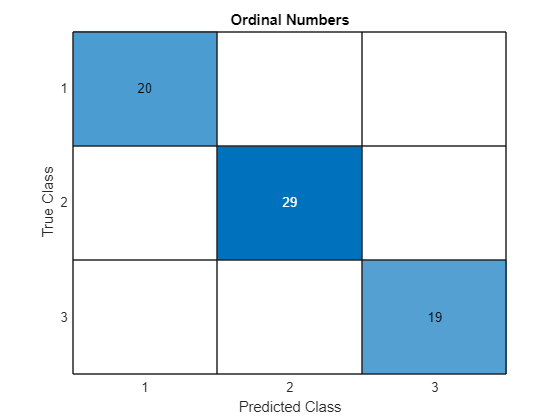


% Option 2 (Ordinal Numbers)
X = table(:, ord_feat);
y = table(:, labels);

%% Split Data for Option 2
[train_idx,~,test_idx] = dividerand(height(X),0.8,0,0.2);
Xtrain = X(train_idx,:);
ytrain = y(train_idx,:);
Xtest = X(test_idx,:);
ytest = y(test_idx,:);

%% Train and test model for Option 2
model = fitctree(Xtrain,ytrain);
yP = predict(model,Xtest);

%% Show confusion chart for Option 2
confusionchart(table2array(ytest),yP);
title('Ordinal Numbers');

From these confusion matrix charts, you can see that One-hot encoding only performs slightly worse, but it takes a lot of requirement on the computer. On the other hand Ordinal Numbers performs very well and is computationally easier.

**Improved Classification:** The result of the case study is improved classification with feature engineering.

**References**

- Agrawal, D., [**Crystal System Properties for Li-ion batteries**](https://www.kaggle.com/divyansh22/crystal-system-properties-for-liion-batteries), Properties of Li-ion silicate to predict the crystal system class of the battery, Kaggle, March 2020.